Load Data

trial_folder = "igor_08_12_2020"

trial_folder = "igor_08_12_2020"


all_channels = load(trial_folder + "/eeg_data.csv");
used_electrodes = all_channels(:, 1:5);
sorted_electrodes = zeros(size(used_electrodes));

sorted_electrodes(:, 1) = used_electrodes(:, 4);
sorted_electrodes(:, 2) = used_electrodes(:, 5);
sorted_electrodes(:, 3) = used_electrodes(:, 3);
sorted_electrodes(:, 4) = used_electrodes(:, 1);
sorted_electrodes(:, 5) = used_electrodes(:, 2);

file = fopen(trial_folder + "/slice_index.txt", "r");
line_count = 0;
line = 0;

labels = [];
start_indexes = [];
end_indexes = [];

while true
    line = fgetl(file);
    if line == -1
        break
    end
    line_count = line_count + 1;
    
    if line_count > 2
        elements = strsplit(line, ",");
        cell1 = elements(1);
        cell2 = elements(2);
        cell3 = elements(3);
        
        label = str2double(cell1{:});
        start_index = str2double(cell2{:});
        end_index = str2double(cell3{:});
        
        labels = [labels, label];
        start_indexes = [start_indexes, start_index];
        end_indexes = [end_indexes, end_index];
    end
end

Fs = 250;

Filter

average = mean(sorted_electrodes);
for i=1:5
    sorted_electrodes(:, i) = sorted_electrodes(:, i) - average(i);
end

filtered_data = bandstop(sorted_electrodes, [49, 51], Fs);
filtered_data = bandpass(filtered_data, [16, 18], Fs);
filtered_data = filtered_data';

Plot data and FFT

trial_number = 5

trial_number = 5

first_sample = start_indexes(trial_number);
last_sample = end_indexes(trial_number);
upper_bound = 150;
current_label = labels(trial_number)

current_label = 1

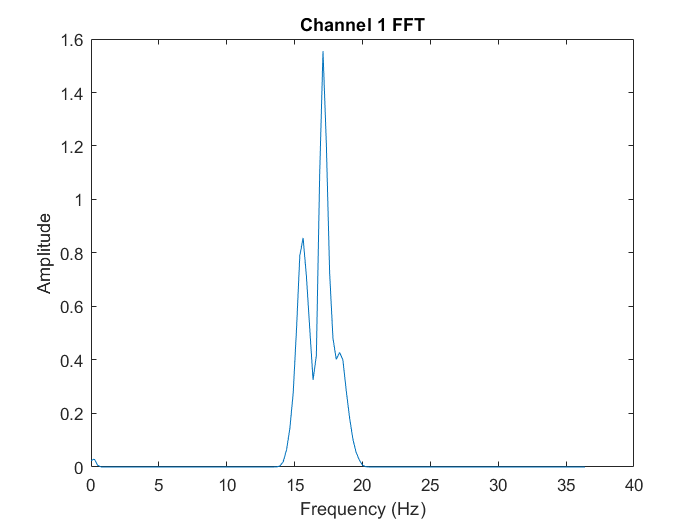

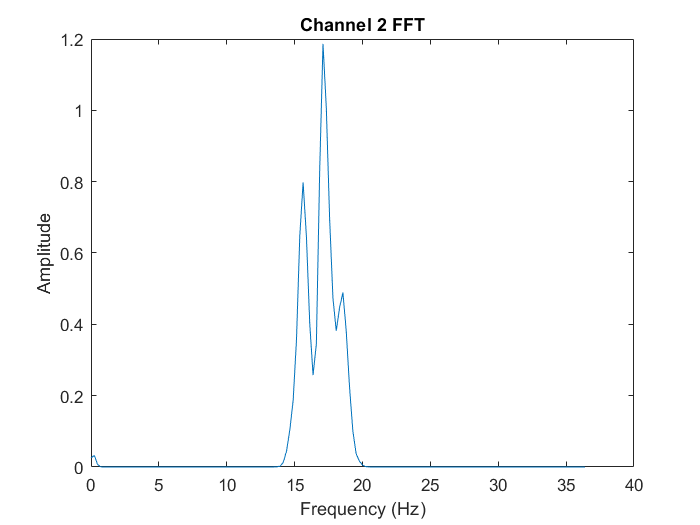

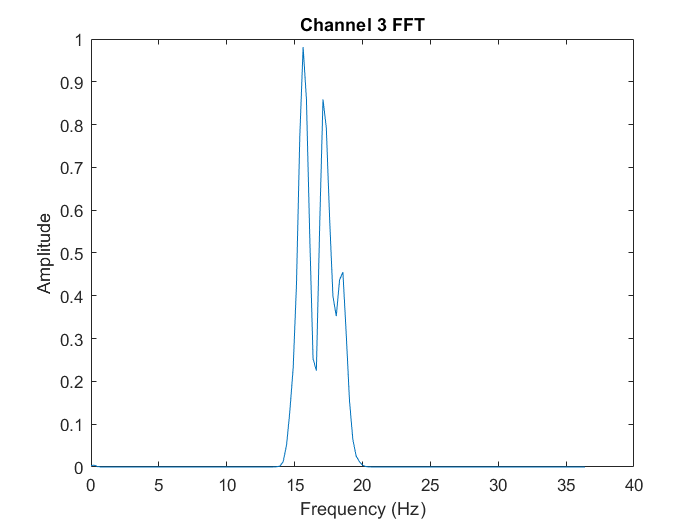

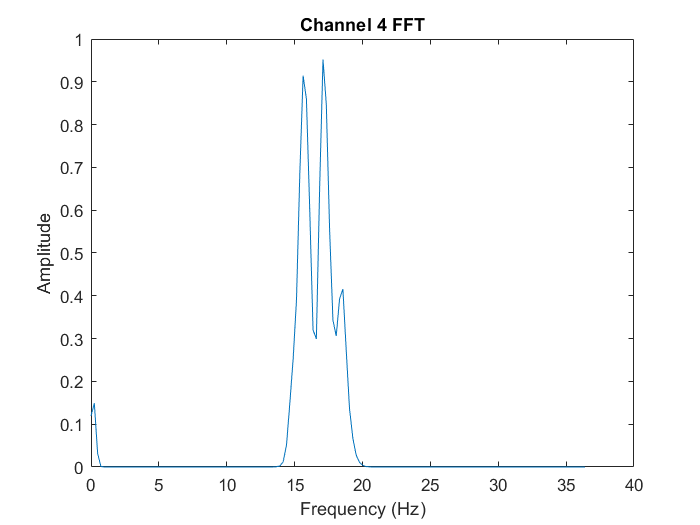

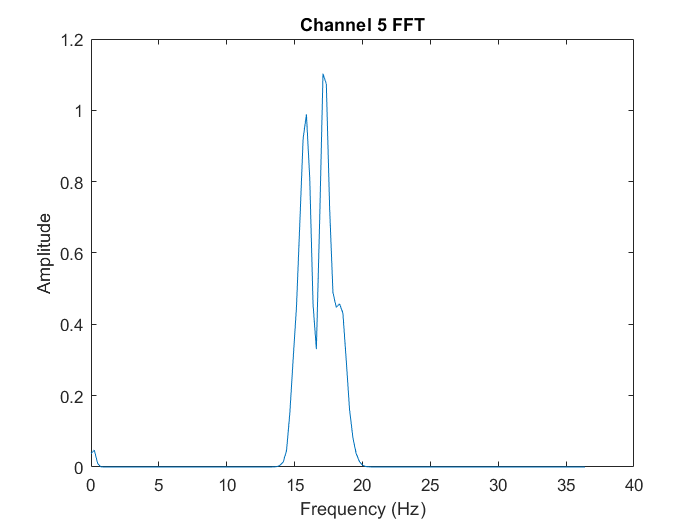

N = last_sample - first_sample;
t = (first_sample:last_sample) / Fs;
window_size = 4 * Fs;
most_left = [];
most_right = [];
for i=1:5
    current_data = filtered_data(i, first_sample:last_sample);
    %Y = 1/N * abs(fft(current_data));
    %Y = Y(1:N/2);
    %freq = (0:N/2 - 1) * Fs/N;
    [power, freq] = pwelch(current_data, [], [], [], Fs);
    
    if i==1
        most_left = power;
    end
    
    if i==5
        most_right = power;
    end
    
    figure;
    
    plot(freq(1:upper_bound), power(1:upper_bound));
    title("Channel " + i + " FFT")
    xlabel("Frequency (Hz)")
    ylabel("Amplitude")
end

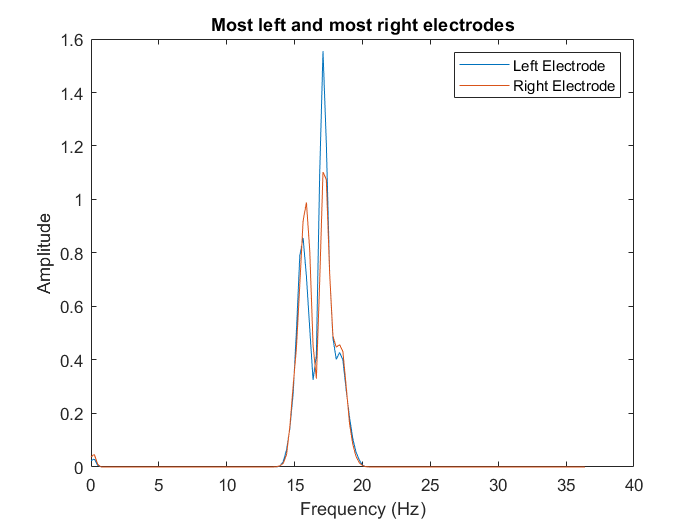


figure;
plot(freq(1:upper_bound), most_left(1:upper_bound))
hold on;
plot(freq(1:upper_bound), most_right(1:upper_bound))
title("Most left and most right electrodes")
xlabel("Frequency (Hz)")
ylabel("Amplitude")
legend("Left Electrode", "Right Electrode")

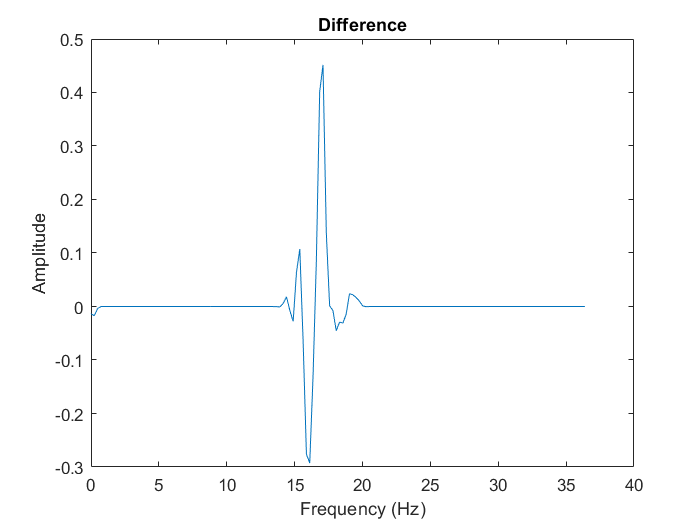

diff = most_left - most_right;
figure;
plot(freq(1:upper_bound), diff(1:upper_bound))
title("Difference")
xlabel("Frequency (Hz)")
ylabel("Amplitude")